# ALL - ROBUSTNESS - MODEL UNCERTAINTY (INF)

## realvleospacecraft0UB

%models
loop_real = 'realvleospacecraft0UB_mpcpd';
loop_model = 'realvleospacecraft0_mpcpd_model';
sc_real = 'realvleospacecraft0UB';
sc_model = 'realvleospacecraft0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;
tar = 3;
costfunction = 1;

%disturbances
disturbances;

%mpcpd params
pred_horizon = 200;
cont_update = 250;
g = [1; 1; 1; 50; 50; 50];

### realvleospacecraft0

1_realvleospacecraft0UB_nodist_1

%info
filename = '1_realvleospacecraft0UB_nodist_1';
info = '1: 200 250 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2) with realvleospacecraft0 model';

%params
iterations = 25;
learning_rate = 0.1;

%disturbance
tau_dist_ser = no_tau_dist_ser;

%sim
simmpcpd;

prepvisualise;

%clean
close all;
clear;

## realvleospacecraft0LB

%models
loop_real = 'realvleospacecraft0LB_mpcpd';
loop_model = 'realvleospacecraft0_mpcpd_model';
sc_real = 'realvleospacecraft0LB';
sc_model = 'realvleospacecraft0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;
tar = 3;
costfunction = 1;

%disturbances
disturbances;

%mpcpd params
pred_horizon = 200;
cont_update = 250;
g = [1; 1; 1; 50; 50; 50];

### realvleospacecraft0

1_realvleospacecraft0LB_nodist_1

%info
filename = '1_realvleospacecraft0LB_nodist_1';
info = '1: 200 250 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2) with realvleospacecraft0 model';

%params
iterations = 25;
learning_rate = 0.1;

%disturbance
tau_dist_ser = no_tau_dist_ser;

%sim
simmpcpd;

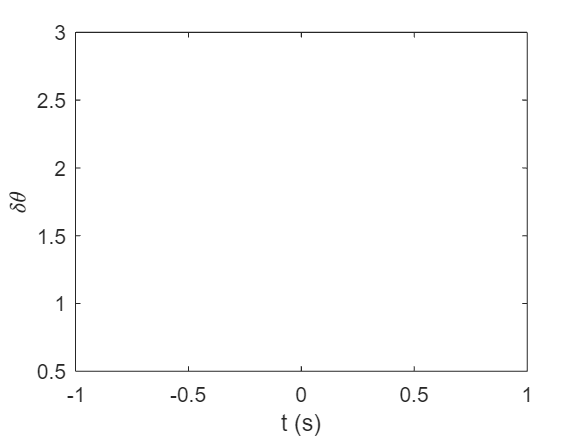

Error using matlab.internal.math.getdimarg
Dimension argument must be a
positive integer scalar within
indexing range.

Error in cumtrapz>getDimArg (line 91)
    dim = matlab.internal.math.getdimarg(dim);

Error in cumtrapz (line 49)
    dim = min(ndims(y)+1, getDimArg(

prepvisualise;


%clean
close all;
clear;